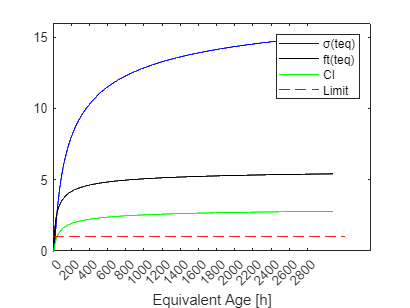

nsamples = 10;
Ea = 31000 + (33000*rand(nsamples,1)); %=========== Activation Energy [J/mol]
R = 8.31; %======================================== Gas constant [J/mol K]
Tenv = 25 + 273; %================================= Environmental temperature [K]
Tref = 20 + 273; %================================= Reference temperature [K]
time = (0:1:2160)'; %============================== Time [h] (for "teq" calculation)
sz_time = size(time,1); %========================== Size of time/temperature data
s = 0.20 + (0.18*rand(nsamples,1)); %============== Eurocode parameter that depends on the classification of the cement used [ ]
t0 = 0.5 + (9.5*rand(nsamples,1)); %=============== Setting time [h]
nft = 0.50 + (0.50*rand(nsamples,1)); %============ Variable to calculate the Tensile Strength evolution of concrete[ ]
nEc = 0.30 + (0.20*rand(nsamples,1)); %============ Variable to calculate the Young's Modulus evolution of concrete [ ]
neau = 1; %======================================== Variable to calculate the Autogenous Shrinkage evolution of concrete [ ]
fck = 52.5; %====================================== Characteristic Compressive Strength of concrete [MPa]
ft28 = normrnd(4.90,0.65,nsamples,1); %============ 28-day Tensile Strength of concrete [MPa]
Ec28 = normrnd(46800,2901.60,nsamples,1); %======== 28-day Young's Modulus of concrete [MPa]
eauInf = 0.00008 + (0.0006474*rand(nsamples,1)); %= Autogenous Shrinkage strain in infinite time  [m/m]
CI = nan(sz_time,nsamples); %====================== Cracking Index

CI = crackindexA1 (Ea, R, Tenv, Tref, time, sz_time, nsamples, s, t0, nft, nEc, neau, ft28, Ec28, eauInf);


disp(CI);

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN    0.0002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN    0.0142       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0002
       NaN    0.0539       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0069
       NaN    0.1196       NaN       NaN       NaN       NaN       NaN    0.0057       NaN    0.0241
    0.0341    0.1993       NaN       NaN    0.0000       NaN       NaN    0.0345    0.0316    0.0519
    0.1640    0.2843       NaN       NaN    0.0088       NaN    0.0021    0.0847    0.1514    0.0858
    0.3102    0.3701    0.0000    0.0122    0.0389    0.0671    0.0691    0.1491    0.2810    0.1223
    0.4457    0.4544    0.0042    0.0839    0.0895    0.1514    0.1527    0.2182    0.4219    0.1596
    0.5535    0.5362    0.0189    0.2128    0.1499    0.2510    0.2524    0.2873    0.5480 


A = Ea(:,1)';
B = Tenv(:,1)';
C = s(:,1)';
D = t0(:,1)';
E = nft(:,1)';
F = nEc(:,1)';
G = neau(:,1)';
H = ft28(:,1)';
I = Ec28(:,1)';
J = eauInf(:,1)';


for l = 1:10
     
    if(l == 1)
       Parameters(l,:) = A(1,:);

    elseif(l == 2)
        Parameters(l,:) = B(1,:);
    
    elseif(l == 3)
        Parameters(l,:) = C(1,:);
  
    elseif(l == 4)
        Parameters(l,:) = D(1,:);     

    elseif(l == 5)
        Parameters(l,:) = E(1,:);
    
    elseif(l == 6)
        Parameters(l,:) = F(1,:);

    elseif(l == 7)
        Parameters(l,:) = G(1,:);

    elseif(l == 8)
        Parameters(l,:) = H(1,:);

    elseif(l == 9)
        Parameters(l,:) = I(1,:);
    
    elseif(l == 10)
        Parameters(l,:) = J(1,:);
         
    end
end

%namerow = ["Ea [J/mol]"; "Tenv [K]"; "s"; "tset [h]"; "nft"; "nEc"; "neau"; "fck [MPa]"; "Aggregate Type"; "eauInf"];

%M = [time(73,1); time(169,1); time(337,1); time(673,1); time(1441,1); time(2161,1)];

M = [CI(73,:); CI(169,:); CI(337,:); CI(673,:); CI(1441,:); CI(2161,:)];

writematrix([(Parameters)' (M)'],"CrackingIndex_resultsA1Concrete.txt");
writematrix([(Parameters)' (M)'],"CrackingIndex_resultsA1Concrete.xlsx");